%write the starting and ending position
start_pos = 530100

start_pos = 530100

end_pos = start_pos+2000

end_pos = 532100


%write the experiment state and the count (calculation / happy / sad )
state = "noise" 

state = "noise"

count = "14"

count = "14"


%calculation (0, 1, 2, .....)
%happy(0, 1, 2, .....)


%write the first three letters of your name
my_name_3 = "raf"

my_name_3 = "raf"


%write the name of the file (subject) you want to load
load_file_name = '17201072.txt'

load_file_name = '17201072.txt'



%%%Don't edit unless you know what you are doing
load_file_name_nofmt = erase(load_file_name,'.txt')

load_file_name_nofmt = '17201072'

file_name = state + "_" + load_file_name_nofmt+ "_" + my_name_3 + "_"+ count

file_name = "noise_17201072_raf_14"

file_name_csv = file_name + ".csv"

file_name_csv = "noise_17201072_raf_14.csv"

file_name_png = file_name + ".png"

file_name_png = "noise_17201072_raf_14.png"


x = load(load_file_name)

x =      0     0     0     0     0   668
     1     0     0     0     0   675
     2     0     0     0     0   687
     3     0     0     0     0   703
     4     0     0     0     0   718
     5     0     0     0     0   713
     6     0     0     0     0   699
     7     0     0     0     0   690
     8     0     0     0     0   687
     9     0     0     0     0   685



S=x(:,6);

s = S(start_pos:end_pos)

s =    356
   353
   353
   348
   335
   327
   327
   326
   326
   319


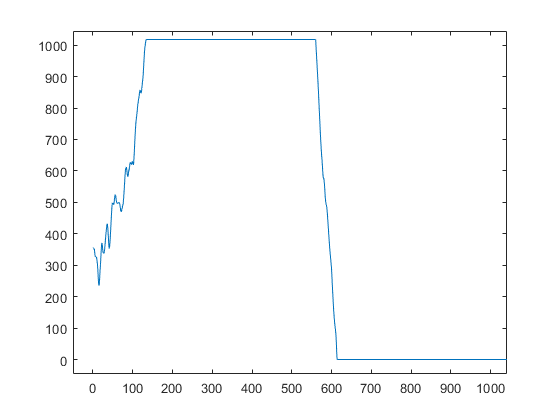

csvwrite(file_name_csv,s)

plot(s);

xlim([-50 1041])
ylim([-46 1045])
print(gcf,file_name_png,'-dpng','-r600');  